%Motor properties and dimensions
L = 0.1; %m
r_m = 0.025; %m
k = 0.5; %W/mK
rho = 8800; %kg/m^3
c = 420; %J/kgK
Power = 1000; %W
efficiency = 0.9;

Volume = pi*(r_m^2)*L; %m^3
egen = (Power-efficiency*Power)/Volume; %W/m^3
alpha = k/(rho*c); %thermal diffusivity

%Air properties
%Ambient air temperature profile with respect to time in seconds from 0 to 1800 
T_a = @(t) (-(7.0263*10^-17)*t.^6 + (3.7942*10^-13)*t.^5 - (6.5001*10^-10)*t.^4 + ...
    (2.9117*10^-7)*t.^3 + (2.4549*10^-4)*t.^2 - ...
    (2.4975*10^-1)*t + (1.4973*10)); %degrees Celsius

%Ambient air pressure profile with respect to time in seconds from 0 to 1800 
P_a = @(t) ((7.6189*10^-14)*t.^6 - (4.1143*10^-10)*t.^5 + (9.9884*10^-7)*t.^4 - ...
    (1.3741*10^-3)*t.^3 + (1.078)*t.^2 - ...
    (4.3423*10^2)*t + (1.0065*10^5)); %Pa

%Ambient air velocity profile with respect to time in seconds from 0 to 1800 
V_a = @(t) ((3.5132*10^-16)*t.^6 - (1.8971*10^-12)*t.^5 + (3.2501*10^-9)*t.^4 - ...
    (1.4559*10^-6)*t.^3 - (1.2275*10^-3)*t.^2 + ...
    (1.2487)*t + (1.3409*10^-1)); %m/s

%Nodes
n_x = 20; %number of nodes in x direction
n_r = 20; %number of nodes in y direction
x = linspace(0, L, n_x); %x direction nodes
r = linspace(0, r_m, n_r); %radial direction nodes
dx = L/(n_x-1); %grid size in x direction
dr = r_m/(n_r-1); %grid size in radial direction

%Initializing with initial conditions (at time = 0 s)
T = T_a(0)*ones(n_x,n_r); %initializing T matrix of size n_x x n_r
T_prev = T;
reflect_initial = flipud(T_prev); %reflecting over the symmetrical plane
T_i = [reflect_initial(2:r,:); T_prev]; %initial temperature of motor
%heatmap(T_i);
%colorbar;

%Temperature dependent fluid properties
R = 287.08;
%Film temperature
T_film = @(t,r,x) ((T_a(t) + T_prev(n_r,n_x))./2 + 273);
%Density
rho_air = @(t,r,x) (P_a(t)./(R.*T_film(t,r,x)));
%Thermal conductivity
k_air = @(t,r,x) (-4.937787e-4 + 1.018087e-4.*T_film(t,r,x)...
    - 4.627937e-8.*(T_film(t,r,x)).^2 + 1.250603e-11.*(T_film(t,r,x)).^3);
%Specific heat
c_p_air = @(t,r,x) (1.045356e3 - 3.161783e-1.*T_film(t,r,x)...
    + 7.083814e-4.*T_film(t,r,x).^2 - 2.705209e-7.*T_film(t,r,x).^3);
%Dynamic viscosity
mu = @(t,r,x) (2.287973e-6 + 6.259793e-8.*T_film(t,r,x)...
    - 3.131956e-11.*(T_film(t,r,x)).^2 + 8.15038e-15.*(T_film(t,r,x)).^3);

%Transient convection heat transfer coefficient
%Reynolds number (for a cylinder)
Re = @(t,r,x) (rho_air(t,r,x).*V_a(t)*(2*r_m)./mu(t,r,x));
%Prandtl number
Pr = @(t,r,x) (mu(t,r,x).*c_p_air(t,r,x)./k_air(t,r,x));
%Nusselt number (for cross-flow over a cylinder)
Nu_cyl = @(t,r,x) (0.3 + ((0.62.*(Re(t,r,x).^0.5).*Pr(t,r,x).^(1/3))./(1+(0.4./Pr(t,r,x)).^(2/3)^0.25)).*(1+(Re(t,r,x)./282000).^(5/8)).^(4.5));
%Nusselt number (for laminar flow over a flat plate)
Nu_plate_lam = @(t,r,x) (0.664*(Re(t,r,x).^0.5).*Pr(t,r,x)^(1/3));
%Nusselt number (for turbulent flow over a flat plate)
Nu_plate_turb = @(t,r,x) (0.037*(Re(t,r,x).^0.8).*Pr(t,r,x)^(1/3));
%Heat transfer coefficients
h_cyl = @(t,r,x) (Nu_cyl(t,r,x).*k_air(t,r,x))./(2*r_m);
h_lam = @(t,r,x) (Nu_plate_lam(t,r,x).*k_air(t,r,x))./(2*r_m);
h_turb = @(t,r,x) (Nu_plate_turb(t,r,x).*k_air(t,r,x))./(2*r_m);

%Time
time_total = 1800; %s
Re(900,ceil(n_r/2),1);
h_cyl_max = h_cyl(900,1,ceil(n_x/2));
h_side_max_ = h_turb(900,ceil(n_r/2),1);
    Ac_sides = 0.5*((pi*r_m^2)-(pi*(r_m-0.5*dr)^2));
    Ac_top = (2*pi*r_m*0.5*dx);
    Ac_bottom = (2*pi*(r_m-0.5*dr)*0.5*dx);
    Vc = Ac_sides*0.5*dx;
primary_coefficient = (-(h_cyl_max*Ac_top)-(h_side_max_*Ac_sides)...
    -(k*Ac_bottom)/(0.5*dr)-(k*Ac_sides)/(0.5*dx))*(1/(rho*Vc*c))

primary_coefficient = -2.9391

dt_max = -1/primary_coefficient %s

dt_max = 0.3402

dt = 0.3; %s
n_time = time_total/dt; %number of time steps
max_temp_vector = zeros(n_time,1);

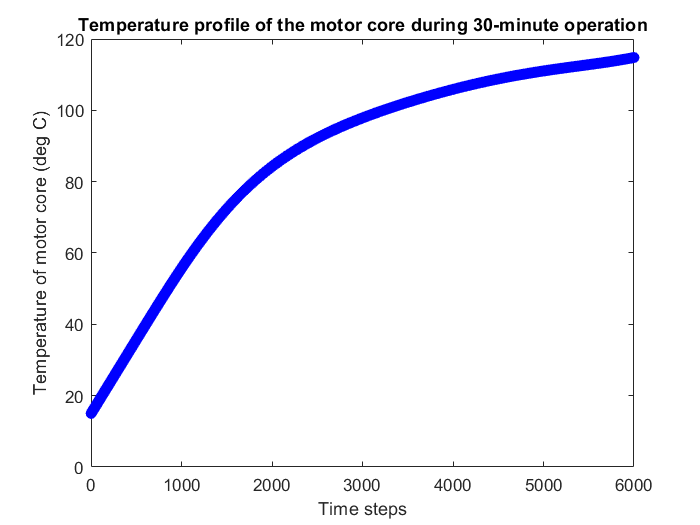

%Explicit method for transient 2D heat transfer
%Time loop
for i = 1:n_time
    T = zeros(n_r, n_x);
    t = i*dt;
    %Corner nodes
    %Element areas and volume (1,1) and (1, n_x)
    Ac_sides = ((pi*r_m^2)-(pi*(r_m-0.5*dr)^2));
    Ac_top = (2*pi*r_m*0.5*dx);
    Ac_bottom = (2*pi*(r_m-0.5*dr)*0.5*dx);
    Vc = Ac_sides*0.5*dx;
    if (Re(t,1,1) < 5*10^5)
        h_2 = h_lam(t,1,1);
    else
        h_2 = h_turb(t,1,1);
    end
    T_film(t,1,1);
    h_1 = h_cyl(t,1,1);
    %Left corner
    T(1,1) = T_prev(1,1) + (egen.*Vc + h_1.*Ac_top.*(T_a(t)-T_prev(1,1))...
        + h_2.*Ac_sides.*(T_a(t)-T_prev(1,1)) + k.*Ac_bottom.*(T_prev(2,1)-T_prev(1,1))./(0.5*dr)...
        + k.*Ac_sides.*(T_prev(1,2)-T_prev(1,1))./(0.5*dx)).*(dt/(rho*Vc*c));
    %Right corner
    T(1,n_x) = T_prev(1,n_x) + (egen.*Vc + h_1.*Ac_top.*(T_a(t)-T_prev(1,n_x))...
        + h_2.*Ac_sides.*(T_a(t)-T_prev(1,n_x)) + k.*Ac_bottom.*(T_prev(2,n_x)-T_prev(1,n_x))./(0.5*dr)...
        + k.*Ac_sides.*(T_prev(1,n_x-1)-T_prev(1,n_x))./(0.5*dx)).*(dt/(rho*Vc*c));
    %Side central nodes    
    %Element areas and volume (n_r,1) and (n_r, n_x)
    Asc_sides = (pi*(0.5*dr)^2);
    Asc_top = (2*pi*0.5*dr*0.5*dx);
    Vsc = Asc_sides*0.5*dx;
    if (Re(t,n_r,1) < 5*10^5)
        h_2 = h_lam(t,n_r,1);
    else
        h_2 = h_turb(t,n_r,1);
    end
    T_film(t,n_r,1);
    h_1 = h_cyl(t,n_r,1);
    %Left side    
    T(n_r,1) = T_prev(n_r,1) + (egen.*Vsc + h_2.*Asc_sides.*(T_a(t)-T_prev(n_r,1))...
        + k.*Asc_sides.*(T_prev(n_r,2)-T_prev(n_r,1))./(0.5*dx)...
        + k.*Asc_top.*(T_prev(n_r-1,1)-T_prev(n_r,1))./(dr)).*(dt/(rho*Vsc*c));
    %Right side    
    T(n_r,n_x) = T_prev(n_r,n_x) + (egen.*Vsc + h_2.*Asc_sides.*(T_a(t)-T_prev(n_r,n_x))...
        + k.*Asc_sides.*(T_prev(n_r,n_x-1)-T_prev(n_r,n_x))./(0.5*dx)...
        + k.*Asc_top.*(T_prev(n_r-1,n_x)-T_prev(n_r,n_x))./(dr)).*(dt/(rho*Vsc*c));
    %Nodes loop
    for j = 1:n_r %rows 
        if (j>1 && j<n_r)
            %Side non-central nodes
            %Element areas and volume (2,1) -> (n_r-1,1) and (2, n_x) -> (n_r-1, n_x)
            As_sides = ((pi*((n_r-j).*dr+0.5*dr)^2)-(pi*((n_r-j).*dr-0.5*dr)^2));
            As_top = (2*pi*((n_r-j).*dr+0.5*dr)*0.5*dx);
            As_bottom = (2*pi*((n_r-j).*dr-0.5*dr)*0.5*dx);
            Vs = As_sides*0.5*dx;
            if (Re(t,j,1) < 5*10^5)
            h_2 = h_lam(t,j,1);
            else
            h_2 = h_turb(t,j,1);
            end
            T_film(t,j,1);
            h_1 = h_cyl(t,j,1);
            %Left side
            T(j,1) = T_prev(j,1) + (egen.*Vs + k.*As_top.*(T_prev(j-1,1)-T_prev(j,1))./(0.5*dr)...
            + h_2.*As_sides.*(T_a(t)-T_prev(j,1)) + k.*As_bottom.*(T_prev(j+1,1)-T_prev(j,1))./(0.5*dr)...
            + k.*As_sides.*(T_prev(j,2)-T_prev(j,1))./(0.5*dx)).*(dt/(rho*Vs*c));
            %Right side
            T(j,n_x) = T_prev(j,n_x) + (egen.*Vs + k.*As_top.*(T_prev(j-1,n_x)-T_prev(j,n_x))./(0.5*dr)...
            + h_2.*As_sides.*(T_a(t)-T_prev(j,n_x)) + k.*As_bottom.*(T_prev(j+1,n_x)-T_prev(j,n_x))./(0.5*dr)...
            + k.*As_sides.*(T_prev(j,n_x-1)-T_prev(j,n_x))./(0.5*dx)).*(dt/(rho*Vs*c));
        end
        for m = 1:n_x %columns
            if (m>1 && m<n_x)
                %Interior central nodes
                %Element areas and volume (1,2) -> (1,n_x-1)
                Aic_sides = (pi*(0.5*dr)^2);
                Aic_top = (2*pi*0.5*dr*dx);
                Vic = Aic_sides*dx;
                %Interior
                T(n_r,m) = T_prev(n_r,m) + (egen.*Vic + k.*Aic_top.*(T_prev(n_r-1,m)-T_prev(n_r,m))./(dr)...
                + k.*Aic_sides.*(T_prev(n_r,m-1)-T_prev(n_r,m))./(dx)...
                + k.*Aic_sides.*(T_prev(n_r,m+1)-T_prev(n_r,m))./(dx)).*(dt/(rho*Vic*c));
            
                %Top nodes
                %Element areas and volume (1,2) -> (1,n_x-1)
                At_sides = ((pi*(r_m)^2)-(pi*(r_m-0.5*dr)^2));
                At_top = (2*pi*r_m*dx);
                At_bottom = (2*pi*(r_m-0.5*dr)*dx);
                Vt = At_sides*dx;
                if (Re(t,1,m) < 5*10^5)
                    h_2 = h_lam(t,1,m);
                else
                    h_2 = h_turb(t,1,m);
                end
                T_film(t,1,m);
                h_1 = h_cyl(t,1,m);
                %Top
                T(1,m) = T_prev(1,m) + (egen.*Vt + h_1.*At_top.*(T_a(t)-T_prev(1,m))...
                + k.*At_sides.*(T_prev(1,m-1)-T_prev(1,m))./(dx)...
                + k.*At_bottom.*(T_prev(2,m)-T_prev(1,m))./(0.5*dr)...
                + k.*At_sides.*(T_prev(1,m+1)-T_prev(1,m))./(dx)).*(dt/(rho*Vt*c));
            end
                        
            if (m>1 && m<n_x && j>1 && j<n_r)
                %Interior non-central nodes
                %Element areas and volume (2,2) -> (2,n_x-1) and (2,2) -> (n_r-1,2)
                Ai_sides = ((pi*((n_r-j).*dr+0.5*dr)^2)-(pi*((n_r-j).*dr-0.5*dr)^2));
                Ai_top = (2*pi*((n_r-j).*dr+0.5*dr)*dx);
                Ai_bottom = (2*pi*((n_r-j).*dr-0.5*dr)*dx);
                Vi = Ai_sides*dx;
                %Interior
                T(j,m) = T_prev(j,m) + (egen.*Vi + k.*Ai_top.*(T_prev(j-1,m)-T_prev(j,m))./(dr)...
                + k.*Ai_sides.*(T_prev(j,m-1)-T_prev(j,m))./(dx) + k.*Ai_bottom.*(T_prev(j+1,m)-T_prev(j,m))./(dr)...
                + k.*Ai_sides.*(T_prev(j,m+1)-T_prev(j,m))./(dx)).*(dt/(rho*Vi*c));
            end
        end
    end    
    T_prev = T;
    T_whole4 = [T;flipud(T)]; 
    max_temp_vector(i) = T(20,10);
    plot(i,max_temp_vector(i,1), 'bo');
    xlabel("Time steps");
    ylabel("Temperature of motor core (deg C)");
    title("Temperature profile of the motor core during 30-minute operation");
    hold on;
end
hold off

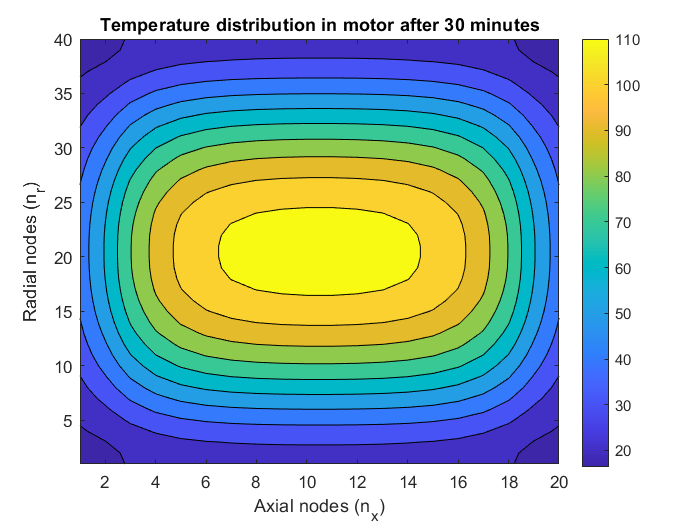

contourf(1:n_x, 1:2*n_r, T_whole4);
colorbar;
hold on
xlabel("Axial nodes (n_x)");
ylabel("Radial nodes (n_r)");
title("Temperature distribution in motor after 30 minutes");
hold off;

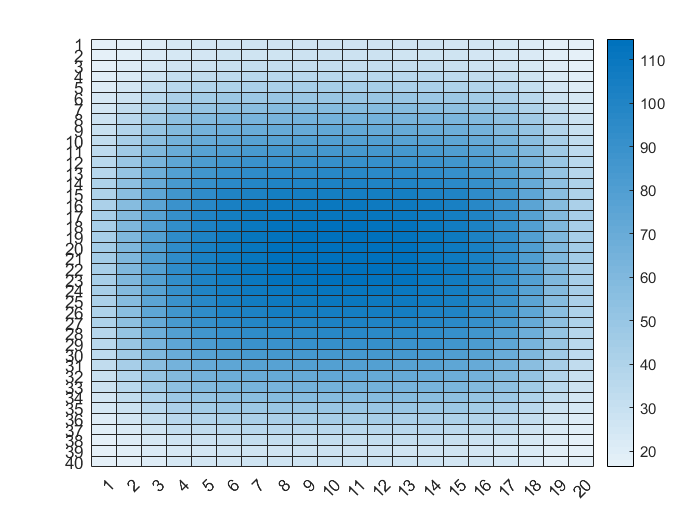

heatmap(T_whole4);
colorbar;

T_max = T(20,10)

T_max = 114.8149